# RoadRunner - Simulink cosimulation: 制御アルゴリズムの比較

## 変数、RoadRunnerをクリーンアップ

if exist("rrApp", "var")
    if class(rrApp) == "roadrunner"
        rrApp.close();
    end
end
if exist("rrSim", "var")
    delete(rrSim);
end
close all;
clear;

## RoadRunnerをMATLABから起動する

rrApp = roadrunner();

% 必要なシナリオファイル, behaviorファイルをコピー
rrProjectPath = rrApp.status.Project.Filename;
copyfile("pathFollowingUtil/TrajectoryFollowBehavior14DoF.rrbehavior.rrmeta",fullfile(rrProjectPath,"Assets/Behaviors/"));
copyfile("pathFollowingUtil/slopeTest14DoF.rrscene", fullfile(rrProjectPath, "Scenes/"));
copyfile("pathFollowingUtil/slopeTest14DoF.rrscenario", fullfile(rrProjectPath, "Scenarios/"));

behaviorName = "TrajectoryFollowBehavior14DoF.rrbehavior";
% シナリオを起動　シーンはシナリオと紐づいているため、自動でシーンも開く
rrApp.openScenario("slopeTest14DoF");
rrApp.setScenarioVariable("EgoVehicleBehavior", "<PROJECT>/Assets/Behaviors/" + behaviorName); %behaviorファイルを設定

rrSim = rrApp.createSimulation();

Connection status: 1
Connected to RoadRunner Scenario server on localhost:36110, with client id {8cef715f-0b8e-4cea-93d8-06e9d8757884}


setRRSCameraMode(rrApp, "follow", actorID=1);

rrSim.set("PacerStatus", "Off");
rrSim.set("MaxSimulationTime", 14);
set(rrSim,"Logging","on");

% RoadRunnerの情報をSimulinkで取得するため、Busオブジェクトを定義
% To support Reader and Writer blocks, some bus objects must be loaded
loadRoadRunnerBusObject();

addpath("pathFollowingUtil");
helperSLTrajectoryFollowerWithRRScenarioSetup(); %車両ダイナミクスパラメータや制御パラメータを設定
% % Simulinkのモデルを開く
model_name = 'TrajectoryFollowVehicleWith14DoF.slx';
open_system(model_name);


% RoadRunnerとSimulinkの実行ステップサイズを揃える
timeStep = 0.01;
RRtimeStep = 0.1;
rrSim.set("StepSize", RRtimeStep);

## モデル予測制御で車両を制御

useDynamicsStanley = true; %シナリオの軌跡通りに動かすSimulinkモデル
vehicleVariant = "3DOF";

% RoadRunnerから車両初期値を取得し、車両モデルにセット
helperSLTrajectoryFollowerWithRRScenarioSetup("rrAppObj", rrApp,...
    "scenarioSimulationObj", rrSim, "behaviorName", behaviorName, ...
    controlMode="mpc_mod");

state_init = mpcstate(mpc_base);

   Assuming no disturbance added to measured output #2.
   Assuming no disturbance added to measured output #1.
   Assuming no disturbance added to measured output #3.


state_init.Plant = [egoInitialPoseCG.CurrVelocity 0,...
    0, 0,...
    deg2rad(egoInitialPoseCG.CurrYawRate) 0];%Vx, ax, Vy, Yaw(rad), YawRate(rad/s), Y
state_init.Covariance = eye(6, 6) * 0.01;

% Simulationを開始する
set(rrSim,"SimulationCommand","Start");
% RoadRunner ScenarioのSimulation実行が終了するまで待機
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end

error("stop");

% logを取得
rrLog = get(rrSim,"SimulationLog");

% 車両の速度を取得
velocityAgent3 = get(rrLog,'Velocity','ActorID',1); % Actor1の速度取得
time3 = [velocityAgent3.Time];% Actor1の時刻取得

% 車両の動きを取得
poseActor3 = rrLog.get('Pose','ActorID',1);
positionActor3_x = arrayfun(@(x) x.Pose(1,4),poseActor3);
positionActor3_y = arrayfun(@(x) x.Pose(2,4),poseActor3);

## 比較プロット

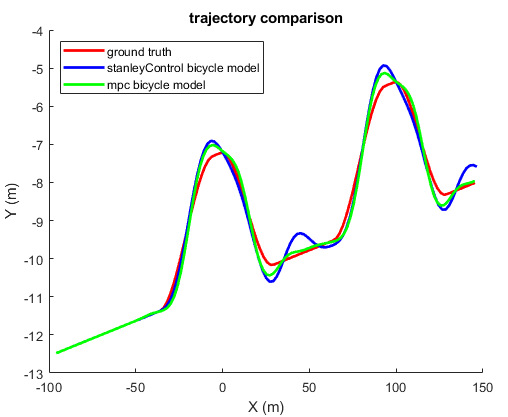

figure;
helperPlotVelocity(time1, velocityAgent1, time2, velocityAgent2, time3, velocityAgent3);
title("EgoSpeed: groundTruth");

helperPlotTrajectory(positionActor1_x, positionActor1_y, positionActor2_x, positionActor2_y, positionActor3_x, positionActor3_y);

## MPC objectの作成

舵角とヨー角は小さい前提での線形化

$\[
 \frac{d}{dt}
\left[  {\begin{array}{cc}
V_x \\
\tilde{a_x} \\
V_y \\
\psi \\
\dot \psi \\
Y
\end{array} } \right]  =
  \left[ {\begin{array}{cc}
     0 & 1 & \dot \psi & 0 & 0 & 0\\
      0 & \frac{-1}{\tau} & 0 & 0 & 0 & 0\\ 
     0 & 0 & -\frac{(2C_f+2C_r)}{mV_x} & 0 & -V_x-\frac{(2C_fl_f-2C_rl_r)}{mV_x} &0 \\
     0 & 0 & 0 & 0& 1 & 0 \\
     0 & 0 & -\frac{(2C_fl_f-2C_rl_r)}{I_zV_x} & 0 &-\frac{(2C_fl_f^2+2C_rl_r^2)}{I_zV_x} & 0 \\
     0 & 0 & 1 & Vx & 0 & 0 \\
  \end{array} } \right]
\left[  \begin{array}{cc}
V_x \\
\tilde{a_x}  \\
V_y \\
\psi \\
\dot \psi \\
Y
\end{array} \right]
\]$$\[
+\  
\left[ {\begin{array}{cc}
 0 & 0 \\
 \frac{1}{\tau} & 0 \\
 0 & \frac{2C_f}{m}\\
 0 & 0 \\
 0 & \frac{2C_fl_f}{I_z}\\
 0 & 0
\end{array} } \right]
\left[ {\begin{array}{cc}
a \\
\delta
\end{array} } \right]
\]
$,    $\[
C = 
\left[ {\begin{array}{cc}
1 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 1 \\
0 & 0 & 0 & 1 & 0 & 0
\end{array} } \right]
\]
$,    $D = 0$


$$y= \left[  {\begin{array}{cc}
V_x \\
Y \\
\psi \\
\end{array} } \right]  = C \left[  {\begin{array}{cc}
V_x \\
\tilde{a_x} \\
V_y \\
\psi \\
\dot \psi \\
Y
\end{array} } \right]$$



$$\[
 \frac{d}{dt}
\left[  {\begin{array}{cc}
V_x \\
\tilde{a_x} \\
V_y \\
\psi \\
\dot \psi \\
Y
\end{array} } \right]  =
  \left[ {\begin{array}{cc}
     0 & 1 & \dot \psi & 0 & 0 & 0\\
      0 & \frac{-1}{\tau} & 0 & 0 & 0 & 0\\ 
     0 & 0 & -\frac{(2C_f+2C_r)}{mV_x} & 0 & -V_x-\frac{(2C_fl_f-2C_rl_r)}{mV_x} &0 \\
     0 & 0 & 0 & 0& 1 & 0 \\
     0 & 0 & -\frac{(2C_fl_f-2C_rl_r)}{I_zV_x} & 0 &-\frac{(2C_fl_f^2+2C_rl_r^2)}{I_zV_x} & 0 \\
     0 & 0 & 1 & Vx & 0 & 0 \\
  \end{array} } \right]
\left[  \begin{array}{cc}
V_x \\
\tilde{a_x}  \\
V_y \\
\psi \\
\dot \psi \\
Y
\end{array} \right]
+\  
\left[ {\begin{array}{cc}
 0 & 0 \\
 \frac{1}{\tau} & 0 \\
 0 & \frac{2C_f}{m}\\
 0 & 0 \\
 0 & \frac{2C_fl_f}{I_z}\\
 0 & 0
\end{array} } \right]
\left[ {\begin{array}{cc}
a \\
\delta
\end{array} } \right]
, C = 
\left[ {\begin{array}{cc}
1 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 1 \\
0 & 0 & 0 & 1 & 0 & 0
\end{array} } \right]
, D = 0
\]$$



$$\[
 \frac{d}{dt}
\left[  {\begin{array}{cc}
V_x \\
\tilde{a_x} \\
V_y \\
\psi \\
\dot \psi \\
Y
\end{array} } \right]  =
  \left[ {\begin{array}{cc}
     0 & 1 & \dot \psi & 0 & 0 & 0\\
      0 & \frac{-1}{\tau} & 0 & 0 & 0 & 0\\ 
     0 & 0 & -\frac{(2C_f+2C_r)}{mV_x} & 0 & -V_x-\frac{(2C_fl_f-2C_rl_r)}{mV_x} &0 \\
     0 & 0 & 0 & 0& 1 & 0 \\
     0 & 0 & -\frac{(2C_fl_f-2C_rl_r)}{I_zV_x} & 0 &-\frac{(2C_fl_f^2+2C_rl_r^2)}{I_zV_x} & 0 \\
     0 & 0 & 1 & Vx & 0 & 0 \\
  \end{array} } \right]
\left[  \begin{array}{cc}
V_x \\
\tilde{a_x}  \\
V_y \\
\psi \\
\dot \psi \\
Y
\end{array} \right]
+\  
\left[ {\begin{array}{cc}
 0 & 0 \\
 \frac{1}{\tau} & 0 \\
 0 & \frac{2C_f}{m}\\
 0 & 0 \\
 0 & \frac{2C_fl_f}{I_z}\\
 0 & 0
\end{array} } \right]
\left[ {\begin{array}{cc}
a \\
\delta
\end{array} } \right]
, C = 
\left[ {\begin{array}{cc}
1 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 1 \\
0 & 0 & 0 & 1 & 0 & 0 \\
0 & 0 & 0 & 0 & 1 & 0
\end{array} } \right]
, D = 0
\]$$


Vx = 20; % Vx初期値　Adaptiveなので毎時更新される
psi_dot = 0; % psi初期値　Adaptiveなので毎時更新される
tau = 0.5;
Ac = [0 1 psi_dot 0 0 0;
     0 -1/tau 0 0 0 0;
     0 0 -(2*Cf+2*Cr)/(m*Vx) 0 -Vx-(2*Cf*lf - 2*Cr*lr)/(m*Vx) 0;
     0 0 0 0 1 0;
     0 0 -(2*Cf*lf-2*Cr*lr)/(Iz*Vx) 0 -(2*Cf*lf^2+2*Cr*lr^2)/(Iz*Vx) 0;
     0 0 1 Vx 0 0];
Bc = [0 0; 1/tau 0; 0 2*Cf/m; 0 0; 0 2*Cf*lf/Iz; 0 0];
% Cc = [1 0 0 0 0 0; 0 0 0 0 0 1; 0 0 0 1 0 0];
Cc = [1 0 0 0 0 0; 0 0 0 0 0 1; 0 0 0 1 0 0; 0 0 0 0 1 0];
Dc = zeros(size(Cc,1),size(Bc,2));

x_initial = [egoInitialPoseCG.CurrVelocity 0,...
    0, 0,...
    deg2rad(egoInitialPoseCG.CurrYawRate) 0]';%Vx, ax, Vy, Yaw(rad), YawRate(rad/s), Y
u_initial = [0; 0];

二輪モデルの入出力の遅れをモデルに組み込む。今回はステアが１次遅れの場合をモデル化。遅れがないときのステア入力を$\tilde \delta$とすると

$\frac{d}{dt}
{\begin{array}{cc}
\delta
\end{array} } = 
-\frac{1}{\tau}
\delta + 
\frac{1}{\tau}
\tilde \delta$ ($\delta(s) = \frac{1}{\tau s + 1} \tilde \delta$)

これをラグフィルタの状態方程式として$\[
\dot{x}_\ell = A_\ell\,x_\ell + B_\ell u, 
\qquad
y_\ell = C_\ell\,x_\ell + D_\ell\,u.
\qquad
x_\ell = \delta, C_\ell = \left[\begin{array}{cc}
0 \\ 1
\end{array} \right], 
D_\ell = \left[\begin{array}{cc}
1 & 0 \\ 0 & 0
\end{array} \right]
\]$とすると

車両モデルの状態方程式$\[
\dot{x}_s = A_s\,x_s + B_s\,u_s, 
\qquad
y_s = C_s\,x_s + D_s\,u_s.
\]$と合わせて

$\dot{x}_s = A_s\,x_s + B_s\,u_s = A_s\,x_s + B_s(C_\ell\,x_\ell + D_\ell\,u)$, $\[
y_s = C_s\,x_s + D_s(C_\ell\,x_\ell + D_\ell\,u)
\]$より


$$\[
z =
\left[
\begin{array}{c}
x_\ell \\[4pt]
x_s
\end{array}
\right],\quad
\dot z =
\left[
\begin{array}{cc}
A_\ell      & 0           \\[4pt]
B_s C_\ell \, & A_s
\end{array}
\right]
z
+
\left[
\begin{array}{c}
B_\ell     \\[4pt]
B_s\,D_\ell
\end{array}
\right]
u,\quad
y =
\left[
\begin{array}{cc}
D_s\,C_\ell & C_s
\end{array}
\right]
z
+
D_s\,D_\ell\,u.
\]$$


が遅れを考慮した拡大状態方程式となる。

tau2 = 0;
lag = tau2;
sizeExNumSS = 0;
if lag > eps
    Atemp = Ac; Btemp = Bc; Ctemp = Cc; Dtemp = Dc;
    Al = -1/lag; Bl = [0, 1/lag]; Cl = [0; 1]; Dl = [1, 0; 0, 0];
    Ac = [Al, zeros(1, size(Atemp, 2)); Btemp*Cl, Atemp];
    Bc = [Bl; Btemp*Dl];
    Cc = [Dtemp * Cl, Ctemp];
    Dc = Dtemp * Dl;

    x_initial = [0; x_initial];
    sizeExNumSS = 1;
end
%離散時間の状態空間表現は行列指数関数で算出可能　テイラー展開のイメージ (c2dと同じ結果)
nx = size(Ac,1);
nu = size(Bc,2);
M = expm([[Ac Bc]*Ts; zeros(nu,nx+nu)]);
Ad = M(1:nx,1:nx);
Bd = M(1:nx,nx+1:nx+nu);
Cd = Cc;
Dd = Dc;

Y = Cd*x_initial + Dd*u_initial;
DX = Ad*x_initial+Bd*u_initial-x_initial;

plantContinuous = ss(Ac,Bc,Cc,Dc);
Ts = control_timeStep;
plantDiscrete = c2d(plantContinuous, Ts); 

## 信号タイプの設定

制御用，擾乱用，ノイズ用など信号タイプを指定します

% 出力 y(1)=v_x, y(2)=Y, y(3)=psi y(4)=yawrate は測定可能（MeasuredOutput）
% 入力 u(1)=a は操作入力(MV), u(2)=delta は操作入力(MV)
mpcPlant = plantDiscrete;
mpcPlant = setmpcsignals(mpcPlant,'MV',1:2,'MO',1:4);

mpc_base = mpc(mpcPlant, Ts, 10, 3);
modelZero = ss([],[],[],zeros(4), Ts);
setoutdist(mpc_base, 'model', modelZero);

## 初期値の設定

mpc_base.Model.Nominal.X = x_initial; % 初期状態
mpc_base.Model.Nominal.U = u_initial;       % 初期入力
mpc_base.Model.Nominal.Y = Y;       % 初期出力

## 重みと制約の設定

性能に影響を与える重みや操縦量／出力の制約を設定します。

% 重み設定
mpc_base.Weights.ManipulatedVariables    = [0.1 0.1];   % MV 重み [accel, steer]
mpc_base.Weights.ManipulatedVariablesRate= [0.1 0.1];    % MV 変化率重み [accel rate, steer rate]
mpc_base.Weights.OutputVariables          = [0.1 0.5 2 0.2];      % MO 重み Vx Y yaw yaw rate

% 入力制約（例：加速度と舵角の制限）
mpc_base.MV(1).Min = -max_dc;   mpc_base.MV(1).Max = max_ac;
mpc_base.MV(2).Min = min_steer;    mpc_base.MV(2).Max = max_steer;

制約は$E u (k+j|k) + Fy(k+j|k) \le G + \epsilon$で設定可能。横加速度$|a_y|\le6 $の制約を設定する。

$a_y = V_x\dot\phi$として

E_mpc = zeros(2, 2);
F_mpc = [0, 0, 0, 1;
     0, 0, 0, -1];
G_mpc = [6; 6] / Vx; %Vxは各シミュレーションステップごとにアップデート
setconstraint(mpc_base, E_mpc, F_mpc, G_mpc);

## 擾乱・ノイズモデルの設定

外乱（例えば車輪摩擦変動）や測定ノイズをモデル化します

% 入力摂動モデル（乱流・摩擦変動など）設定するにはUnmeasured DisturbanceやMeasured
% Disturbanceをsetmpcsignalsで設定しておく必要がある
% Q_inDist = ss([],[],[],eye(6, 6)*0.1);
% setindist(mpc_base, "model", Q_inDist);　プロセスノイズへの影響

% 出力摂動モデル
% setoutdist(mpc_base, model=ss([],[],[],eye(3,3)*0.01));

% 計測ノイズ
mpc_base.Model.Noise = eye(4, 4) .* [0.01, 0.01, 0.01, 10]; % プロセスノイズQ, 測定ノイズRに影響
% mpc_base.Model.Noise = eye(4, 4) .* [1, 1, 1, 1]; % プロセスノイズQ, 測定ノイズRに影響
mpc_base.Model.Noise = eye(4, 4) * 0.1;

% 内部のカルマンフィルタのカルマンゲインを確認
[L, M] = getEstimator(mpc_base);
L %予測ステップで使用される　L * 計測値との誤差

L =     1.4355    0.0000   -0.0000   -0.0000
    5.5269    0.0000   -0.0000   -0.0000
    0.0000   -6.1772  -15.7815   -0.0018
    0.0000    0.7035    1.6253    0.0002
    0.0000    2.5242    7.3598    0.0015
    0.0000    1.3315    1.7983    0.0002


M % 修正状態量 = 状態量 + M * 計測値との誤差

M =     0.8237   -0.0000    0.0000   -0.0000
    6.7505   -0.0000    0.0000   -0.0000
   -0.0000   -0.9554    0.1064    0.0017
    0.0000    0.3606    0.6354    0.0000
   -0.0000    4.4255   12.6810    0.0024
   -0.0000    0.6368    0.3606    0.0000


## 入出力の名前や単位の設定（オプション）

mpc_base.Model.Plant.InputName = {'acceleration', 'steer'};
mpc_base.Model.Plant.InputUnit = {'m/ss', 'rad'};

if lag > eps
mpc_base.Model.Plant.StateName = {'steer'; 'long_speed'; 'tire_accel'; 'lat_speed'; 'yaw'; 'yaw_rate'; 'Y position'};
mpc_base.Model.Plant.StateUnit = {'rad'; 'm/s'; 'm/ss'; 'm/s'; 'rad'; 'rad/s'; 'm'};
else
mpc_base.Model.Plant.StateName = {'long_speed'; 'tire_accel'; 'lat_speed'; 'yaw'; 'yaw_rate'; 'Y position'};
mpc_base.Model.Plant.StateUnit = {'m/s'; 'm/ss'; 'm/s'; 'rad'; 'rad/s'; 'm'};
end
mpc_base.Model.Plant.OutputName = {'longitudinal speed', 'Y position', 'yaw', 'yaw_rate'};
mpc_base.Model.Plant.OutputUnit = {'m/s', 'm', 'rad', 'rad/s'};

state_init = mpcstate(mpc_base);
state_init.Covariance = eye(6+sizeExNumSS, 6+sizeExNumSS) * 0.1;

## シミュレーションと性能検証

コマンドラインでシミュレーションを実行し，出力 `y` と操作量 `u` を取得します

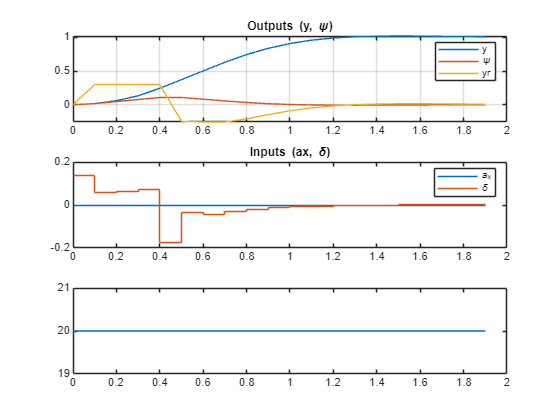

simFlag = true;
if simFlag
    T = 0:Ts:2;             % シミュレーション時間
    r = [20*ones(size(T));     % 速度ステップ目標
         ones(size(T));      %Y位置１を目標
         zeros(size(T));
         zeros(size(T))];    % Yaw角は0

    [y, t, u_initial, xp, xc] = sim(mpc_base, T(end)/Ts, r');  % シミュレーション実行

    % プロット
    figure;
    subplot(3,1,1), plot(t, y(:,2:end)); grid on;
    title('Outputs (y, \psi)');
    legend('y', '\psi', 'yr');
    subplot(3,1,2), stairs(t, u_initial);
    title('Inputs (ax, \delta)');
    legend('a_x','\delta');
    subplot(3,1,3), plot(t, xp(:,1));
end

numReferencePose = 10;

## モデル

元々のモデル

A　システム状態量：9つ,  

B　状態量への入力：2つ

C　状態量からの出力：３つ

D　出力への入力：３つ

状態量： 縦速度$V_x$、縦加速度$\dot{V_x}$, 横速度$V_y$, ヨー角速度$r$, 状態量2つ追加(space control), lag dynamics 3つ(速度, lateral deviation, relative yaw angle),  

入力: 縦加速度$\dot{V_x}$, ステアリング角度$\delta$+curvature disturbance

出力：縦速度$V_x$, 横速度$V_y$, ヨー角速度$r$

useDynamicsStanley = true; %シナリオの軌跡通りに動かすSimulinkモデル
vehicleVariant = "3DOF";

controlMode = 'mpc_mod';%制御モデルを切り替え
% RoadRunnerから車両初期値を取得し、車両モデルにセット
helperSLTrajectoryFollowerWithRRScenarioSetup("rrAppObj", rrApp,...
    "scenarioSimulationObj", rrSim, "behaviorName", behaviorName, ...
    controlMode=controlMode);
numReferencePose = 1;

state_init = mpcstate(mpc_base);
% state_init.Plant = [egoInitialPoseCG.CurrVelocity 0,...
%     0, deg2rad(egoInitialPoseCG.CurrPose(3)),...
%     deg2rad(egoInitialPoseCG.CurrYawRate) egoInitialPoseCG.CurrPose(2)];%Vx, ax, Vy, Yaw(rad), YawRate(rad/s), Y
state_init.Plant = [egoInitialPoseCG.CurrVelocity 0,...
    0, 0,...
    deg2rad(egoInitialPoseCG.CurrYawRate) 0];%Vx, ax, Vy, Yaw(rad), YawRate(rad/s), Y
state_init.Covariance = eye(6, 6) * 0.001;

% Simulationを開始する
set(rrSim,"SimulationCommand","Start");
% RoadRunner ScenarioのSimulation実行が終了するまで待機
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end

The model States, Inputs, and Outputs variables are defined as follows:

- State variables: Lateral velocity $V_y$, yaw angle $\psi$, yaw angle rate $r$, global $Y$ position

- Input variable: Front steering angle $\delta$

- Output variable: Global $Y$ position and yaw angle $\psi$

$\[
  A =
  \left[ {\begin{array}{cc}
-\frac{(2C_f+2C_r)}{mV_x} & 0 & -V_x-\frac{(2C_fl_f-2C_rl_r)}{mV_x} &0 \\
     0 & 0& 1 & 0 \\
     -\frac{(2C_fl_f-2C_rl_r)}{I_zV_x} & 0 &-\frac{(2C_fl_f^2+2C_rl_r^2)}{I_zV_x} & 0 \\
     1 & Vx & 0 & 0 \\
  \end{array} } \right]
\]$,    $\[
B = 
\left[ {\begin{array}{cc}
\frac{2C_f}{m} \\ 0 \\ \frac{2C_fl_f}{I_z} \\ 0
\end{array} } \right]
\]
$,    $\[
C = 
\left[ {\begin{array}{cc}
0 & 0 & 0 & 1 \\
0 & 1 & 0 & 0
\end{array} } \right]
\]
$,    $D = 0$

- State variables: Longitudinal velocity $V_x$, Longitudinal accelration$\dot{V_x}$, Lateral velocity $V_y$, yaw angle $\psi$, yaw angle rate $r$, global $Y$ position

- Input variable: Front steering angle $\delta$

- Output variable: Global $Y$ position and yaw angle $\psi$

$\[
  A' =
  \left[ {\begin{array}{cc}
     0 & 1 & 0 & 0 & 0 & 0\\
      0 & \frac{-1}{\tau} & 0 & 0 & 0 & 0\\ 
     0 & 0 & -\frac{(2C_f+2C_r)}{mV_x} & 0 & -V_x-\frac{(2C_fl_f-2C_rl_r)}{mV_x} &0 \\
     0 & 0 & 0 & 0& 1 & 0 \\
     0 & 0 & -\frac{(2C_fl_f-2C_rl_r)}{I_zV_x} & 0 &-\frac{(2C_fl_f^2+2C_rl_r^2)}{I_zV_x} & 0 \\
     0 & 0 & 1 & Vx & 0 & 0 \\
  \end{array} } \right]
\]$,    $\[
B = 
\left[ {\begin{array}{cc}
 0 & 0 \\
 \frac{1}{\tau} & 0 \\
 0 & \frac{2C_f}{m}\\
 0 & 0 \\
 0 & \frac{2C_fl_f}{I_z}\\
 0 & 0
\end{array} } \right]
\]
$,    $\[
C = 
\left[ {\begin{array}{cc}
1 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 1 \\
0 & 0 & 0 & 1 & 0 & 0
\end{array} } \right]
\]
$,    $D = 0$

$\[
 \frac{d}{dt}
\left[  {\begin{array}{cc}
V_x \\
\tilde{a_x} \\
V_y \\
\psi \\
\dot \psi \\
Y
\end{array} } \right]  =
  \left[ {\begin{array}{cc}
     0 & 1 & \dot \psi & 0 & 0 & 0\\
      0 & \frac{-1}{\tau} & 0 & 0 & 0 & 0\\ 
     0 & 0 & -\frac{(2C_f+2C_r)}{mV_x} & 0 & -V_x-\frac{(2C_fl_f-2C_rl_r)}{mV_x} &0 \\
     0 & 0 & 0 & 0& 1 & 0 \\
     0 & 0 & -\frac{(2C_fl_f-2C_rl_r)}{I_zV_x} & 0 &-\frac{(2C_fl_f^2+2C_rl_r^2)}{I_zV_x} & 0 \\
     0 & 0 & 1 & Vx & 0 & 0 \\
  \end{array} } \right]
\left[  \begin{array}{cc}
V_x \\
\tilde{a_x}  \\
V_y \\
\psi \\
\dot \psi \\
Y
\end{array} \right]
\]$$\[
+\  
\left[ {\begin{array}{cc}
 0 & 0 \\
 \frac{1}{\tau} & 0 \\
 0 & \frac{2C_f}{m}\\
 0 & 0 \\
 0 & \frac{2C_fl_f}{I_z}\\
 0 & 0
\end{array} } \right]
\left[ {\begin{array}{cc}
a \\
\delta
\end{array} } \right]
\]
$,    $\[
C = 
\left[ {\begin{array}{cc}
1 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 1 \\
0 & 0 & 0 & 1 & 0 & 0
\end{array} } \right]
\]
$,    $D = 0$


$$\[
 \frac{d}{dt}
\left[  {\begin{array}{cc}
V_x \\
\dot V_x \\
V_y \\
\psi \\
\dot \psi \\
Y
\end{array} } \right]  =
  \left[ {\begin{array}{cc}
     0 & 1 & 0 & 0 & 0 & 0\\
      0 & \frac{-1}{\tau} & 0 & 0 & 0 & 0\\ 
     0 & 0 & -\frac{(2C_f+2C_r)}{mV_x} & 0 & -V_x-\frac{(2C_fl_f-2C_rl_r)}{mV_x} &0 \\
     0 & 0 & 0 & 0& 1 & 0 \\
     0 & 0 & -\frac{(2C_fl_f-2C_rl_r)}{I_zV_x} & 0 &-\frac{(2C_fl_f^2+2C_rl_r^2)}{I_zV_x} & 0 \\
     0 & 0 & 1 & 0 & 0 & 0 \\
  \end{array} } \right]
\left[  \begin{array}{cc}
V_x \\
\dot V_x \\
V_y \\
\psi \\
\dot \psi \\
Y
\end{array} \right]

+\  
\left[ {\begin{array}{cc}
 0 & 0 \\
 \frac{1}{\tau} & 0 \\
 0 & \frac{2C_f}{m}\\
 0 & 0 \\
 0 & \frac{2C_fl_f}{I_z}\\
 0 & 0
\end{array} } \right]
\left[ {\begin{array}{cc}
a \\
\delta
\end{array} } \right]
+
\left[ {\begin{array}{cc}
0 \\ 0 \\ 0 \\ 0 \\ -V_x \\ 0
\end{array} } \right]
\rho
\]
$$


$\dot Y = V_x\sin\psi + V_y \cos \psi
$となるため、非線形　$e = Y - Y_{ref}
$で表現が必要


$$\dot Y \simeq V_x \psi + V_y
$$



$$\dot e = \dot Y - \dot Y_{ref} = V_y - \dot Y_{ref} =  V_y - \int{a_{yref}} dt
$$


Vx = 20;
A = [0 1 0 0 0 0;
     0 -1/tau 0 0 0 0;
     0 0 -(2*Cf+2*Cr)/(m*Vx) 0 -Vx-(2*Cf*lf - 2*Cr*lr)/(m*Vx) 0;
     0 0 0 0 1 0;
     0 0 -(2*Cf*lf-2*Cr*lr)/(Iz*Vx) 0 -(2*Cf*lf^2+2*Cr*lr^2)/(Iz*Vx) 0;
     0 0 1 0 0 0];
B = [0 0; 1/tau 0; 0 2*Cf/m; 0 0; 0 2*Cf*lf/Iz; 0 0];
C = [1 0 0 0 0 0; 0 0 0 0 0 1; 0 0 0 1 0 0];
D = 0;
vehicle = ss(A,B,C,D);

nx = size(Ac,1);
nu = size(Bc,2);
M = expm([[Ac Bc]*Ts; zeros(nu,nx+nu)]);
A = M(1:nx,1:nx);
B = M(1:nx,nx+1:nx+nu);
C = Cc;
D = Dc;

% Nominal conditions for discrete-time plant
X = x_initial;
U = u_initial;
Y = C*x_initial + D*u_initial;
DX = A*x_initial+B*u_initial-x_initial;

## 車両ダイナミクスとしてフルビークルモデル(14DoF)、制御をStanleyControlで実施

useDynamicsStanley = true; %シナリオの軌跡通りに動かすSimulinkモデル
vehicleVariant = "14DOF";

% controlMode = 'mpc';%制御モデルを切り替え
% numReferencePose = PredictionHorizon; %prediction horizonと同数のreference poseを出力
% RoadRunnerから車両初期値を取得し、車両モデルにセット
helperSLTrajectoryFollowerWithRRScenarioSetup("rrAppObj", rrApp,...
    "scenarioSimulationObj", rrSim, "behaviorName", behaviorName, ...
    controlMode="mpc");

% 事前に作成した地形マップをロード
load("gridMap_groundHeight_RT.mat");% RoadRunnerシーンをstlやfbxなどのメッシュファイルで出力し、２次元高さマップに変換して取得
hegihtMap = "2DMap"; %事前に用意した地形マップを使用するモード
debug_engine3D = false;%trueにするとUnreal Engineによる追加表示あり

% Unreal EngineシーンをEmptyに設定
load_system("sim3d_visualization");
Sim3DConfigPath = "sim3d_visualization/Simulation3DTerrain";
set_param(Sim3DConfigPath, "SourceFile", "");

% Simulationを開始する
set(rrSim,"SimulationCommand","Start");
% RoadRunner ScenarioのSimulation実行が終了するまで待機
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end
% logを取得
rrLog = get(rrSim,"SimulationLog");

% 車両の速度を取得
velocityAgent3 = get(rrLog,'Velocity','ActorID',1); % Actor1の速度取得
time3 = [velocityAgent3.Time];% Actor1の時刻取得

% 車両の動きを取得
poseActor3 = rrLog.get('Pose','ActorID',1);
positionActor3_x = arrayfun(@(x) x.Pose(1,4),poseActor3);
positionActor3_y = arrayfun(@(x) x.Pose(2,4),poseActor3);

rotationActor3_eulZYX = cell2mat(arrayfun(@(x) tform2eul(x.Pose, "ZYX")', poseActor3, 'UniformOutput', false))';
rotationActor3_pitch = rad2deg(rotationActor3_eulZYX(:, 3));

function helperPlotVelocity(time1, velocityAgent1, time2, velocityAgent2, time3, velocityAgent3)
    velMagAgent1 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent1);
    velMagAgent2 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent2);
    velMagAgent3 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent3);


    % Plot the agent velocities with respect to simulation time using the plot function. Label the graph and the x and y axes.
    hold on
    plot(time1,velMagAgent1,"r")
    plot(time2,velMagAgent2,"b")
    plot(time3,velMagAgent3,"g")
    grid on
    title("Agent Velocities from RoadRunner Scenario")
    ylabel("Velocity (m/sec)")
    xlabel("Time (sec)")
    legend(["ground truth","stanleyControl bicyclemodel", "mpc bicyclemodel"], 'Location','southwest');
end
function helperPlotTrajectory(positionActor1_x, positionActor1_y, positionActor2_x, positionActor2_y, positionActor3_x, positionActor3_y)
    % hdMap = getMap(rrSim);
    % lanes = hdMap.map.lanes;
    % Loop through each of the lane specifications using a for loop and plot the lane coordinates.
    
    figure
    hold on
    % for i = 1:numel(lanes)
    %     control_points = lanes(i).geometry.values;
    %     x_coordinates = arrayfun(@(cp) cp.x,control_points);
    %     y_coordinates = arrayfun(@(cp) cp.y,control_points);
    %     plot(x_coordinates, y_coordinates, 'black');
    % end
    plot(positionActor1_x,positionActor1_y,"r","LineWidth",2);
    hold on;
    plot(positionActor2_x,positionActor2_y,"b","LineWidth",2);
    plot(positionActor3_x,positionActor3_y,"g","LineWidth",2);
    legend(["ground truth","stanleyControl bicycle model", "mpc bicycle model"], 'Location','northwest');
    title("trajectory comparison");
    ylabel("Y (m)");
    xlabel("X (m)");
end